# A Cryptographic Schemes for Secret Long-distance Underwater Communications

**Author**: Michel Barbeau

**Date**: April 11, 2023

clear
figure;
% d = 8; % number of distinct permutations
% n = 4; % block size (bits)
d = 64; % number of distinct permutations
n = 8; % block size (bits)
F = 50; % frame size (bits)
m = ceil(F/n); % number of blocks
i = floor( sqrt(2^(m*n)*d^m) )

i = 5.6295e+14

idb = floor( log10(i) )

idb = 14

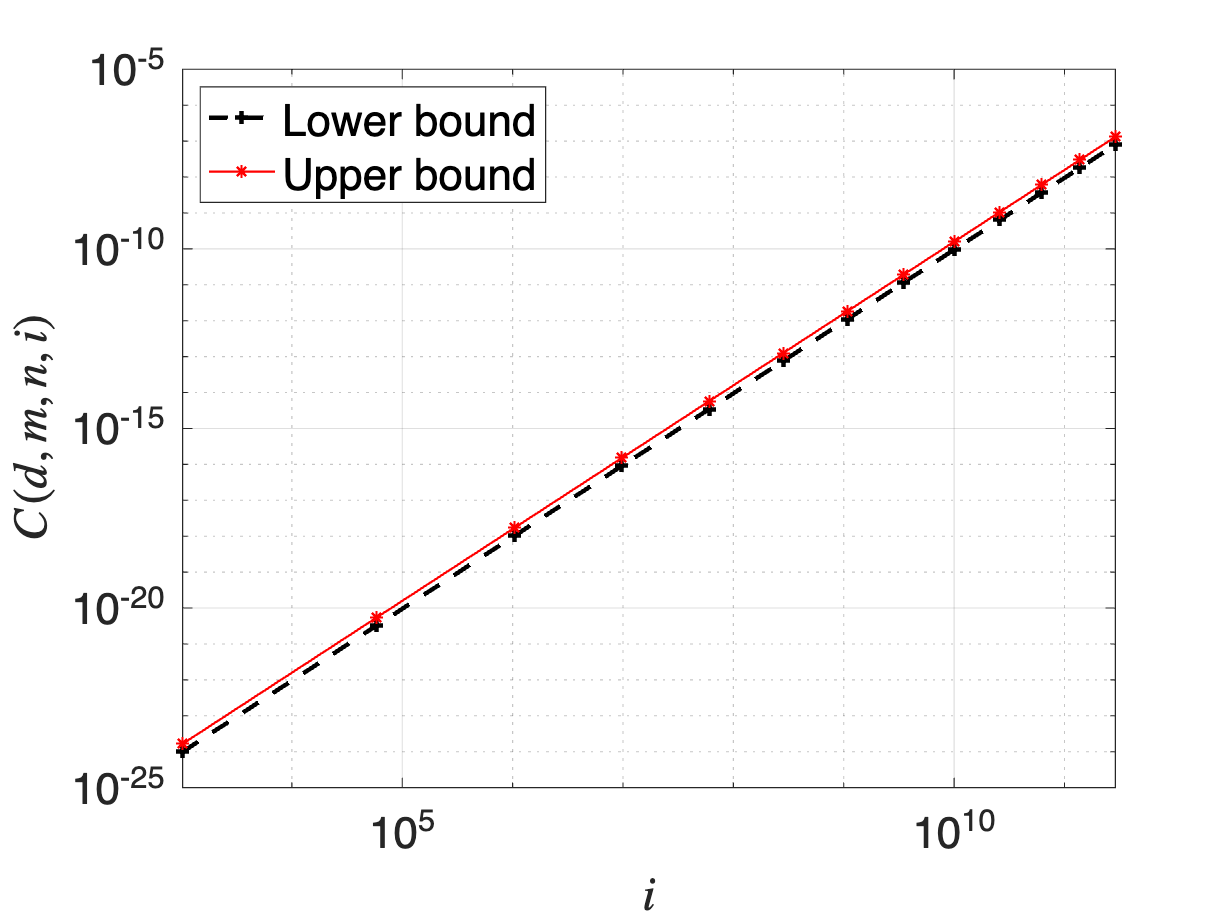

low = zeros(1,idb);
high = zeros(1,idb);
denominator = 2^(m*n+1) * d^m;
for k=1:idb
    i = k^10;
    high(k) = i*(i-1);
    low(k) = 0.6 * high(k) ;
end
x = (1:idb).^10;
loglog(x,low./denominator, '--k+', 'LineWidth', 2, 'MarkerSize',6);
hold on;
loglog(x,high./denominator, '-r*', 'LineWidth', 1, 'MarkerSize',6);
xlabel('$i$','interpreter','latex');
ylabel('$C(d,m,n,i)$','interpreter','latex');
set(gca,"FontSize", 20);
grid on;
legend('Lower bound', 'Upper bound', 'Location','northwest', 'FontSize', 20);

% x2 = [x; flipud(x)];
% fill(x2, [low; flipud(high)], 'g', 'FaceAlpha',0.5); 
% xlim([0 i])
% exportgraphics(gca,'collisionprob.svg');